# Documentation on simulate_and_plot()

First open the project "**AutonomousVehicleModeling.prj**", then run the script "**simulate_and_plot.m**" without giving arguments, the Simulink model "**VehicleFollowing.slx**" will be opened and ran with default setting.

simulate_and_plot();

## Parameters

The parameters that can be set by user are listed below:

- **"position"**: set the initial position of leader and ego vehicle, default is ** [40, 20]**, e.g. leader vehicle starts at **40** m, ego vehicle at **20** m

- **"speed"**: set the initial speed of leader and ego vehicle, default is **[20, 25]**, e.g. leader vehicle starts with **20** m/s, ego vehicle with** 25** m/s 

- **"leader_config"**: set the reference speed and speed disturbance of leader vehicle, default is **[10, 0]**, e.g. leader vehicle's reference speed is **10** m/s, it has an extra **0** **amplitude** **sine-wave** speed disturbance 

- **"controller"**: set the controller of ego vehicle, default is '**MathWorksMPC**'

- **"controller_behavior_MathWorks"**: set the **controller behavior** for **MathWorks MPC**, this parameter is **valid only when controller is MathWorks MPC**, the default is **0.5**

- **"prediction_horizon"**: set the prediction horizon of controllers **other than PID controller**, the default is **10**

- **"time_headway"**: set the time headway of all controllers, the default is **1.4**

- **"acceleration_boundary"**: set the boundary of acceleration of controllers **other than PID controller**, the default is **[2, -3]**, i.e., the maximum longitudinal acceleration is **2** m/s^2, the minimum longitudinal acceleration is **-3** m/s^2

- **"default_spacing"**: set the fixed safety distance between leader and ego vehicle, the default is **10** m

- **"simTime"** : set the simulation time in seconds, the default is **50** s.

The options for controller are:

- '**MathWorksMPC**'

- '**MPC_quadprog**'

- '**MPC_quadprog_wKalman**'

- '**MPC_fmincon**'

- '**MPC_fmincon_wKalman**'

- '**PID**'

 A **Kalman Filter** block is added in the variant subsystem, the controller name '**wKalman**' means '**with Kalman Filter**'.

## Example 1

You can run the example below:

simulate_and_plot("position", [70, 20], 'speed', [20, 15], 'leader_config', [20, 3], 'controller', 'MPC_quadprog','simTime',30);

The **initial position** for leader and ego vehicle is **70 **m and **20 **m, the** initial speed** for leader and ego vehicle is **20** m/s and **15** m/s, the** reference speed** for leader vehicle is also **20** m/s, and it has a **3** m/s sine-wave **speed disturbance**(**see figure below**), the **controller** is '**MPC_quadprog**', so there is no need to set '**controller_behavior_MathWorks**'.

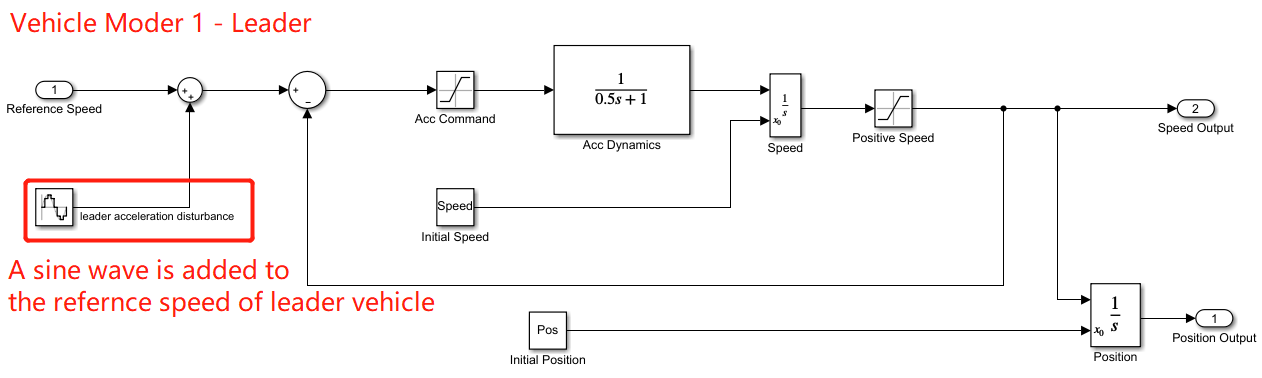

As is depicted by the figure below, when **3** m/s sine wave speed disturbance is added to leader speed, the speed of leader is changing over time.

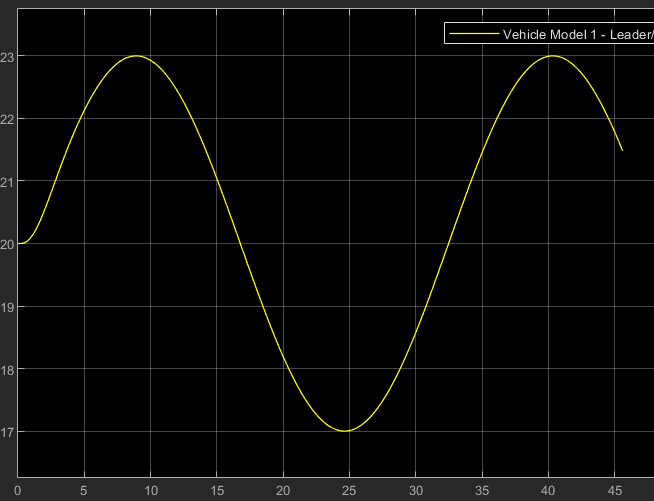

## Example 2

You can also run the example below, the position, speed and controller are all set to default values:

simulate_and_plot("prediction_horizon", 20, 'time_headway', 2, 'acceleration_boundary', [3, -5]);

The prediction horizon is set to **20**, the time headway is set to **2** s, and the maximum and minimum longitudinal acceleration are set to **3** m/s^2 and **-5** m/s^2 respectively.

## **Instruction to set new variant to the variant subsystem**

As is mentioned above, you can set the controller of ego vehicle by giving argument to the "**simulate_and_plot.m**", you can also set the controller with the variant subsystem inside "**Vehicle Model 2 - Following**":

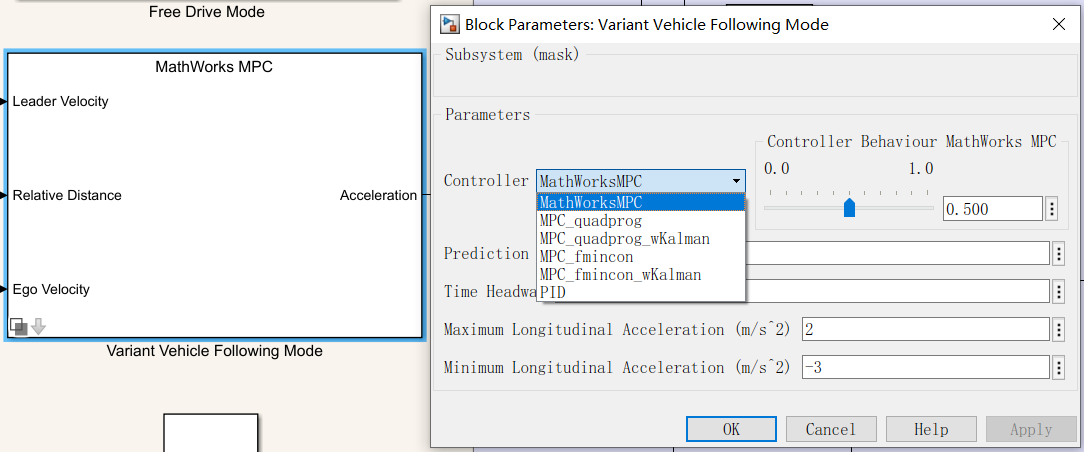

If you want to add a new variant, first right click the "**Variant Vehicle Following Mode**" 

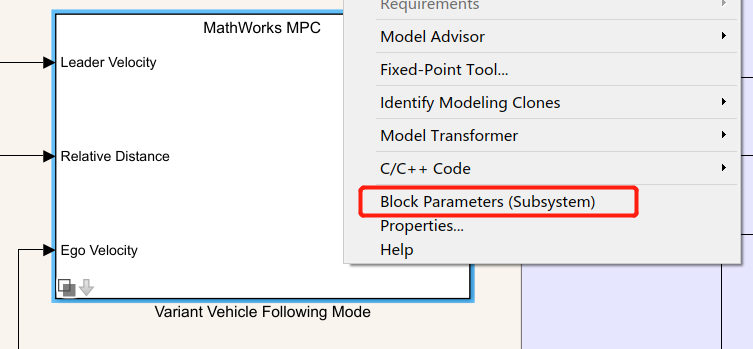

Click "**Create and add a new subsystem variant choice**" and a new variant will be added inside "**Variant Vehicle Following Mode**", then click OK:

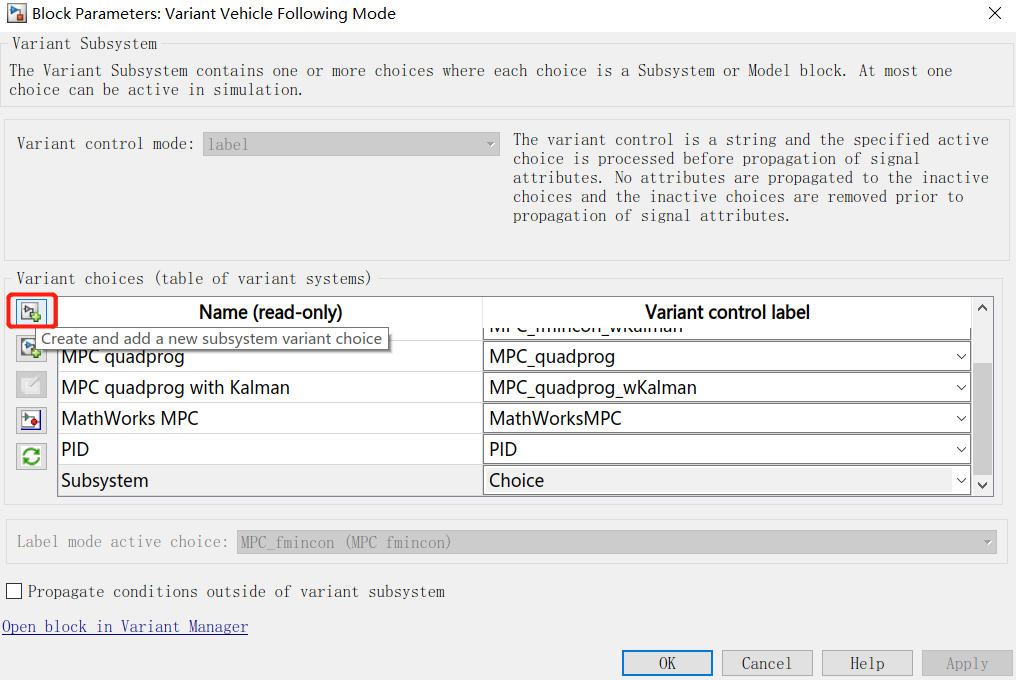

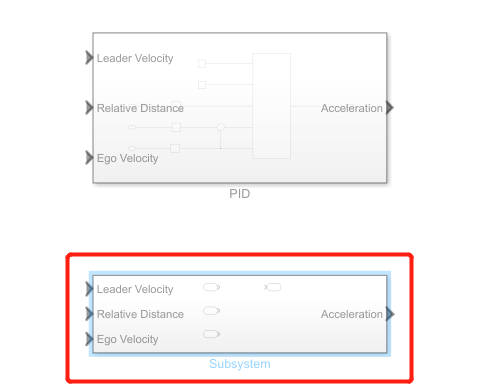

Change the name from "**Subsystem**" to "**Test**" (the name is up to you, and don't forget to put the blocks of new variant inside the "**Test**"):

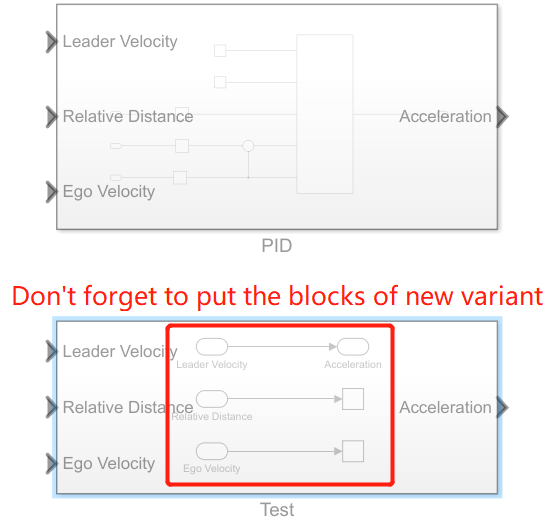

Open "**Block Parameters**" again and change the "**Variant control label**" and click OK:

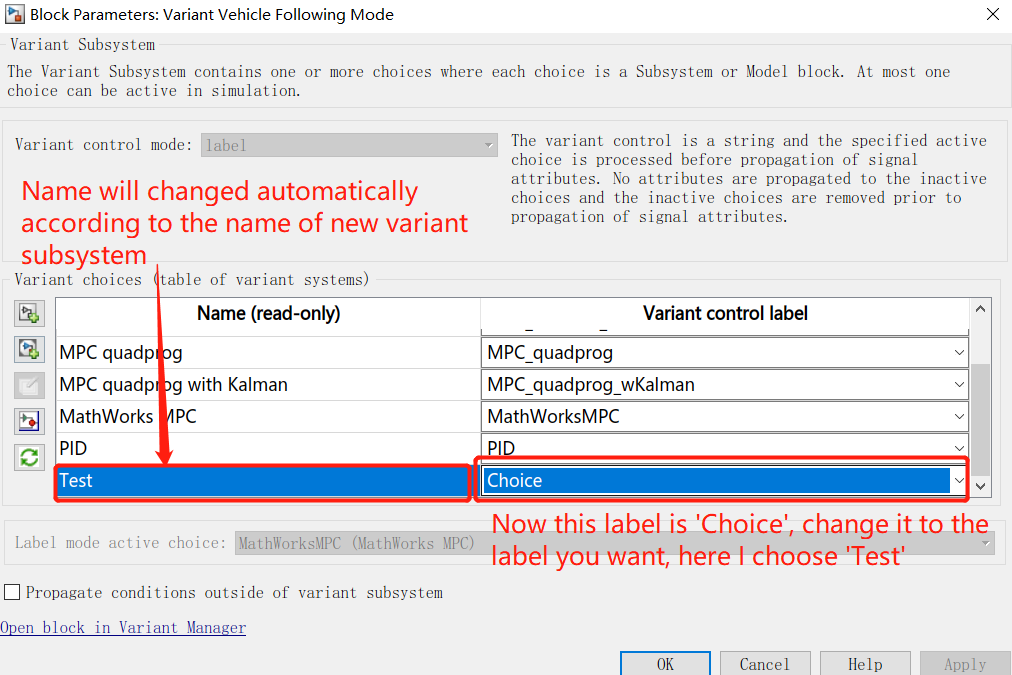

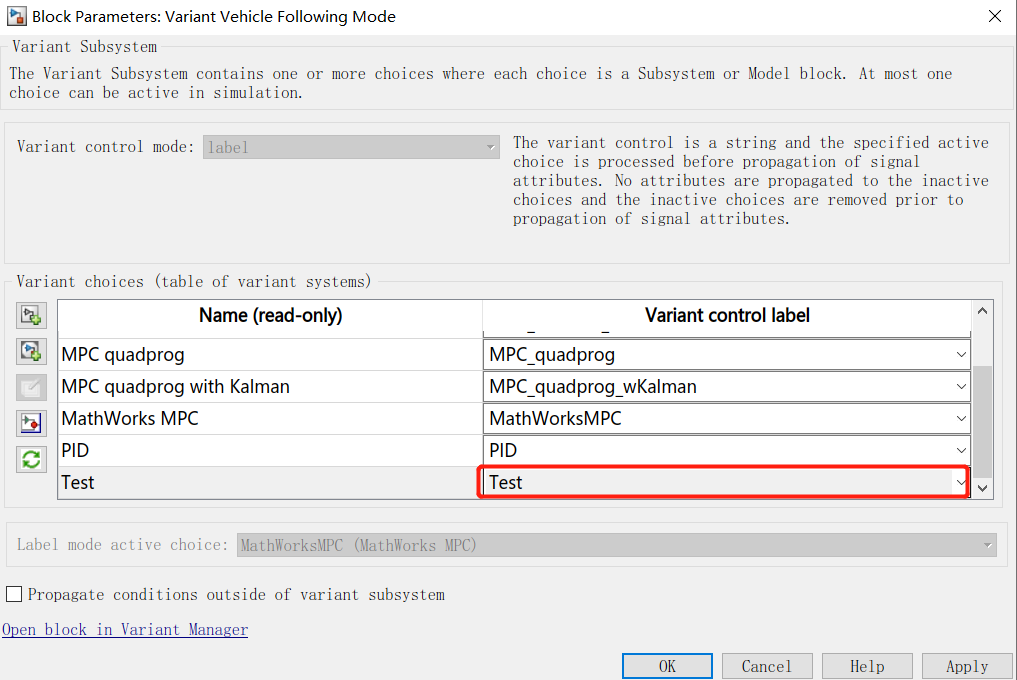

Right click the "**Variant Vehicle Following Mode**", click "**Mask**->**Edit Mask**":

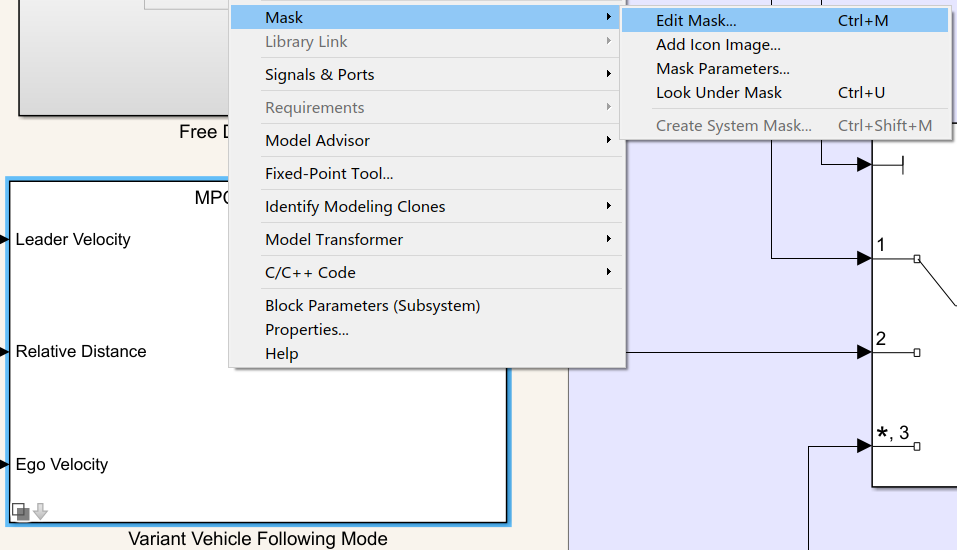

Choose "**Parameter and Dialog**", click "**Controller**" Popup widget:

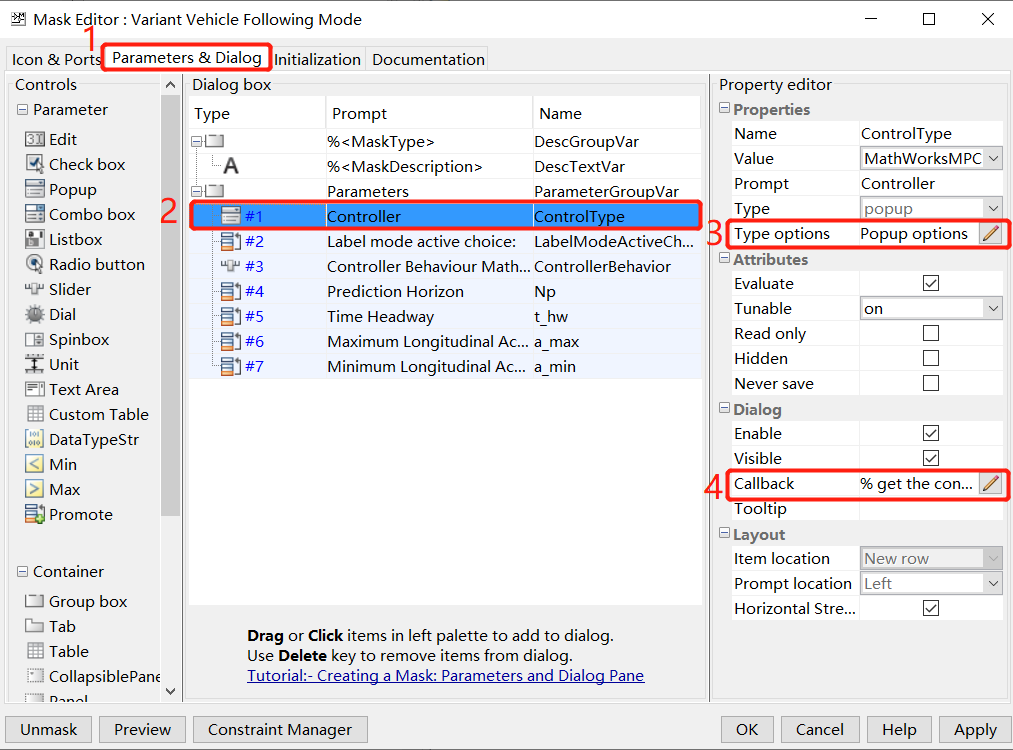

Click the pencil icon of "**Type options**", you can see all the variants label added before new variant "**Test**":

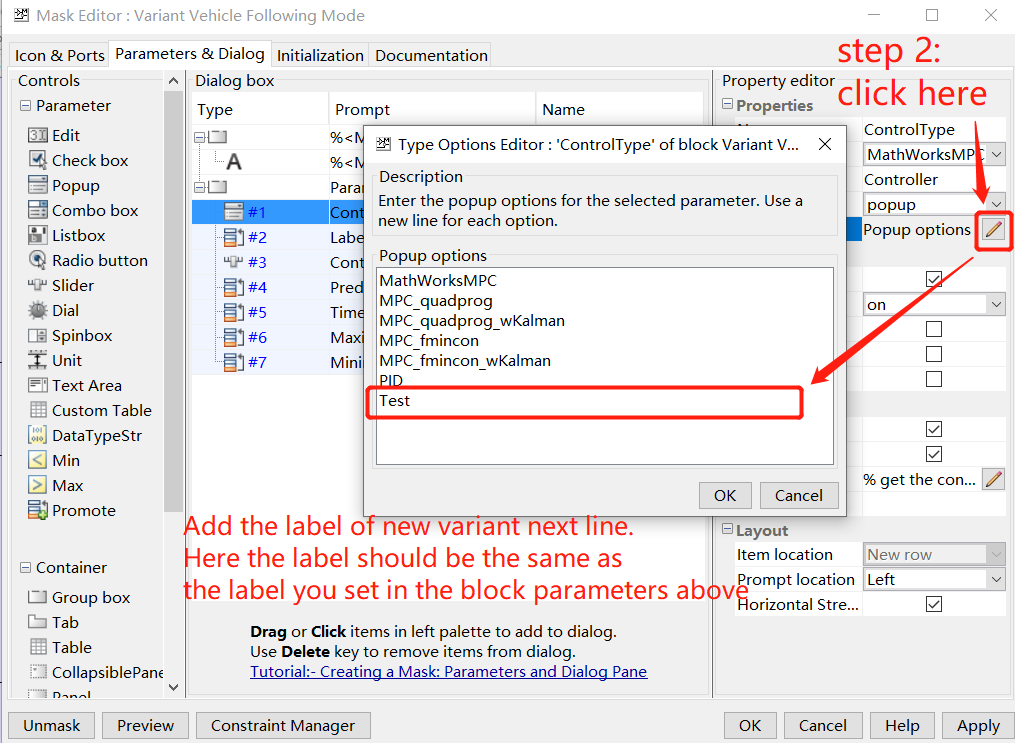

Click "**Callback**" (number 4 in the figure above), you can see the Callback function:

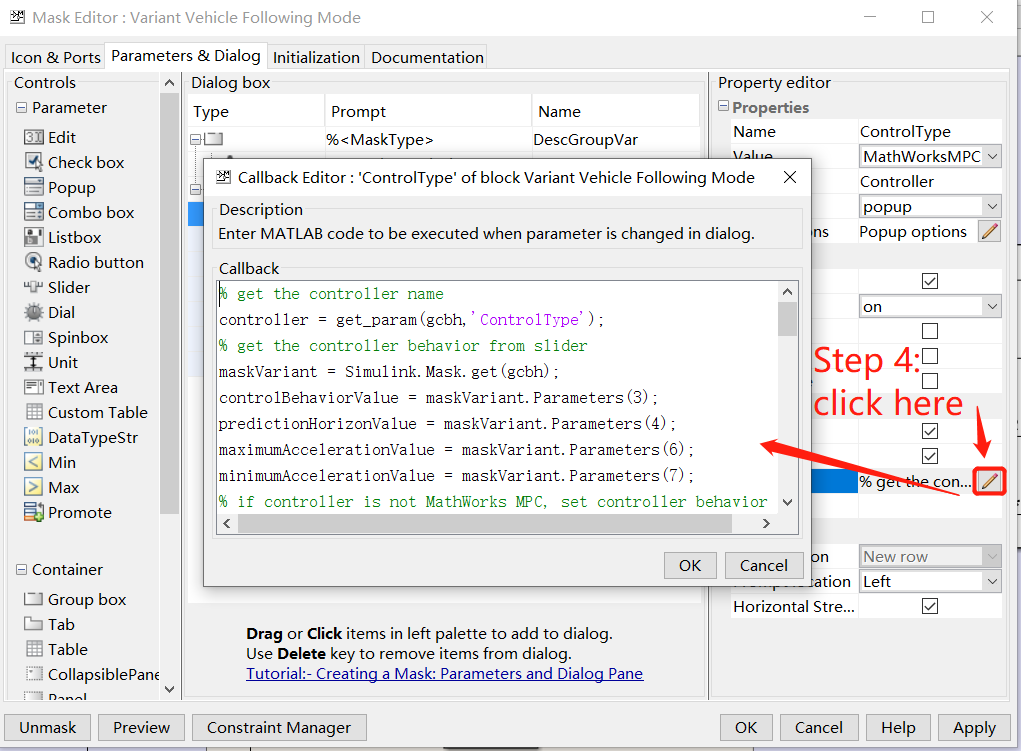

Add a new if statement, click OK, then click OK again:

**elseif strcmp(controller, 'Test')**

**    set_param(gcbh, 'LabelModeActiveChoice', 'Test');**

**    controlBehaviorValue.set('Visible', 'off');**

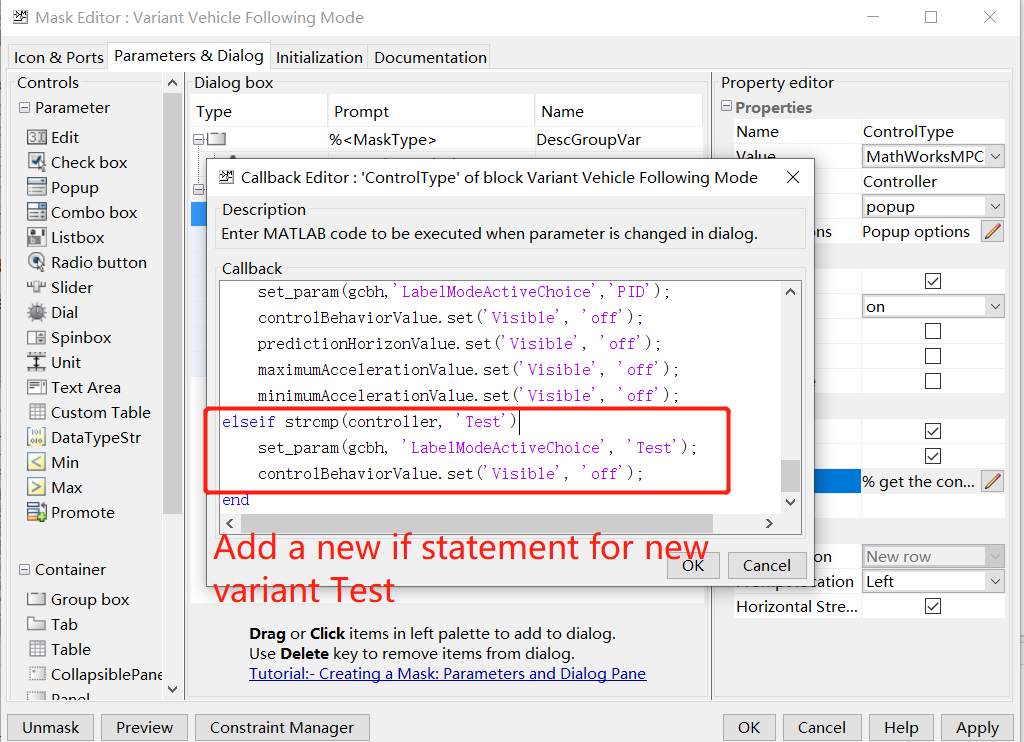

**controlBehaviorValue.set('Visible', 'off');** is used to make the controller behavior slidebar of MathWorks MPC invisible, since this parameter is needed only for MathWorks MPC.

**predictionHorizonValue.set('Visible', 'off');**

**maximumAccelerationValue.set('Visible', 'off');**

**minimumAccelerationValue.set('Visible', 'off');**

The 3 statements above are used to make prediction horizon, maximum and minimum longitudinal acceleration input boxes invisible,  if your new variant needs prediction horizon or the acceleration boundary, then you can modify the if statement to 

**elseif strcmp(controller, 'Test')**

**    set_param(gcbh, 'LabelModeActiveChoice', 'Test');**

**    controlBehaviorValue.set('Visible', 'off');**

**    predictionHorizonValue.set('Visible', 'on');**

**    maximumAccelerationValue.set('Visible', 'on');**

**    minimumAccelerationValue.set('Visible', 'on');**

You can see the new variant you added appearing in the Popup list of the variant subsystem mask:

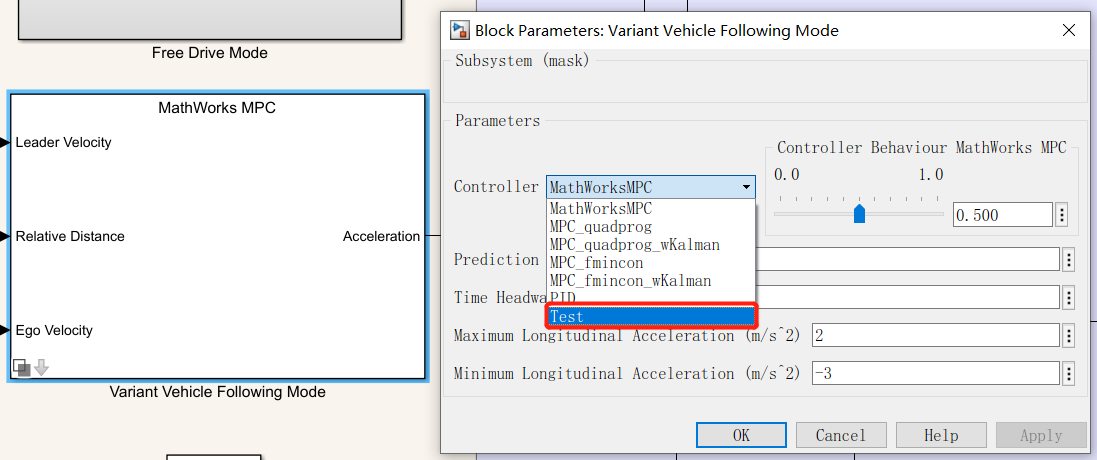

Choose "**Test**" and click OK, the active variant will be switched to "**Test**":

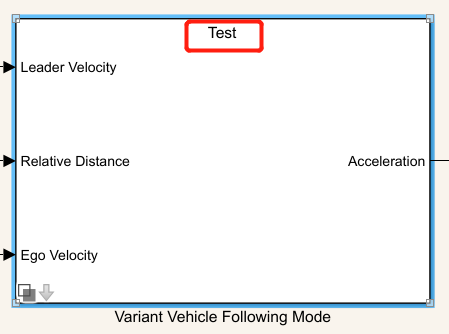

Look under Mask you will see the active variant is "**Test**" now: